g = 9.81;
omega2 = 9;
R = g/omega2;
gamma = 0.5;
omega = 2;

The 1st case: theta0 is 1 and dot{theta}0 is 0.

In both cases, the pendulum reaches a steady SHO motion after some periods. The final steady is independent of the initial condition, and the omega is equal to the force angular frequency. 

theta0 = 1;
thetad0 = 0;
% [t,w] = pendulum4(R,theta0,thetad0,gamma,omega);

[t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma,omega);
% [t1,w1] = pendulum_damp(R,theta0,thetad0,gamma);
ind1 = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1 = 2*mean(diff(t(ind1(length(ind1)-10:length(ind1)-1))))

period1 = 3.1421

omega1 = 2*pi/period1

omega1 = 1.9997

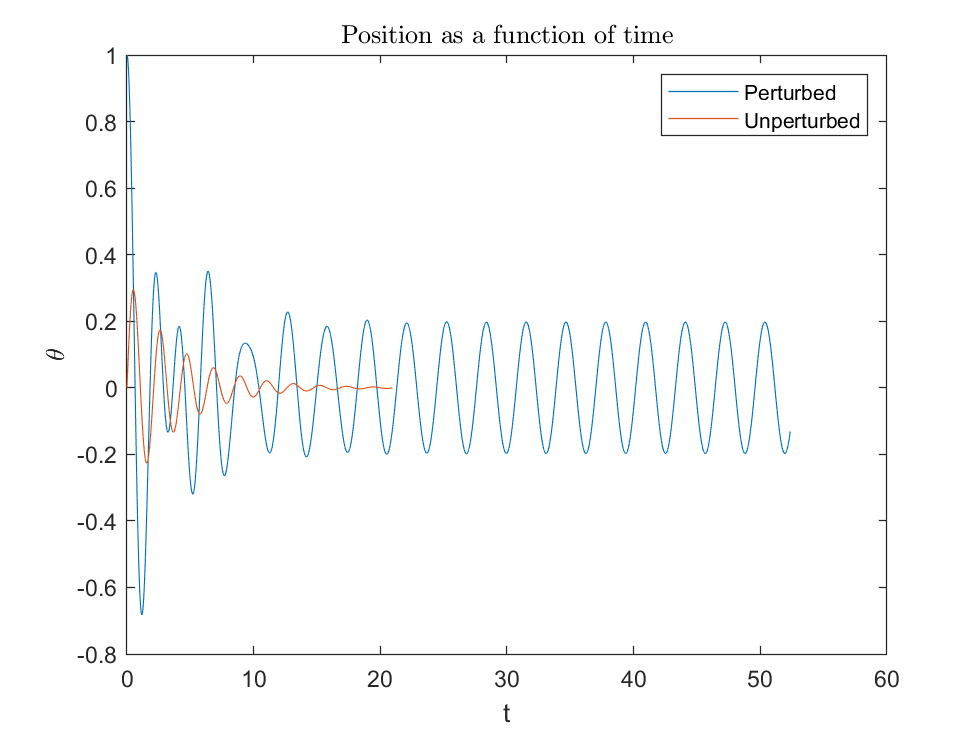

plot(t,w(:,1),t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Perturbed','Unperturbed')
title('Position as a function of time','interpreter','latex')

The 2nd case: theta0 is 0 and dot{theta}0 is 1.

theta0 = 0;
thetad0 = 1;
[t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma,omega);
[t1,w1] = pendulum_damp(R,theta0,thetad0,gamma);
ind1 = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1 = 2*mean(diff(t(ind1(length(ind1)-10:length(ind1)-1))))

period1 = 3.1466

omega1 = 2*pi/period1

omega1 = 1.9968

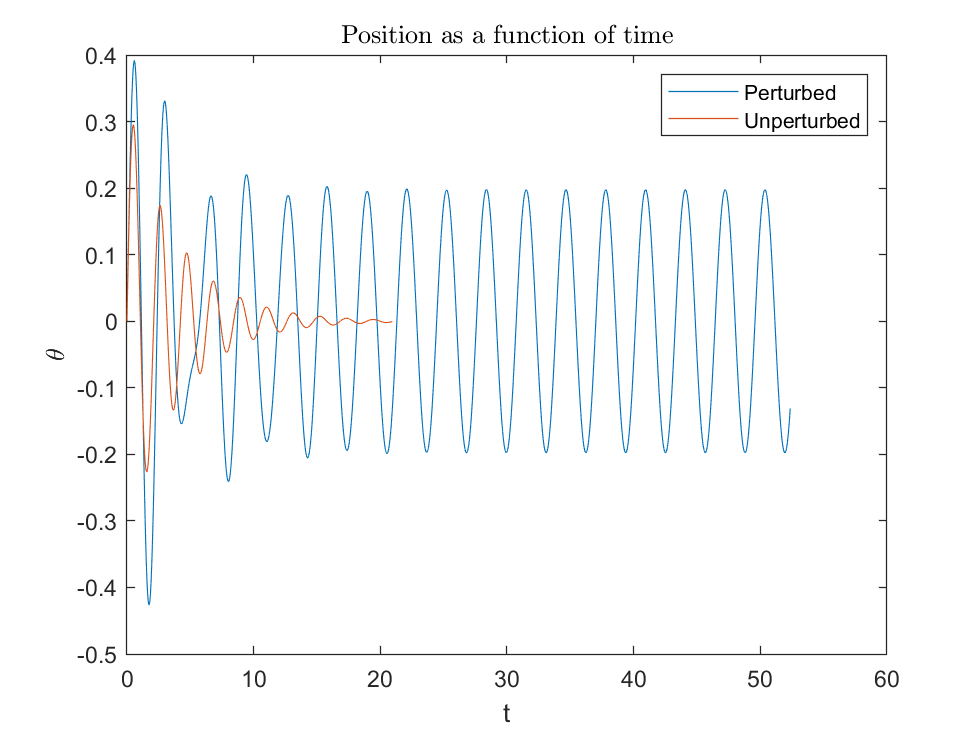

plot(t,w(:,1),t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Perturbed','Unperturbed')
title('Position as a function of time','interpreter','latex')

(b) For two different omega, the pendulum has almost the same augular frequency with the omega. So it depends on the force frequency.

thetad0 = 0;
theta0 = 1;
omega = 1;
[t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma,omega);
ind1 = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1 = 2*mean(diff(t(ind1(length(ind1)-10:length(ind1)-1))))

period1 = 6.2725

omega1 = 2*pi/period1

omega1 = 1.0017

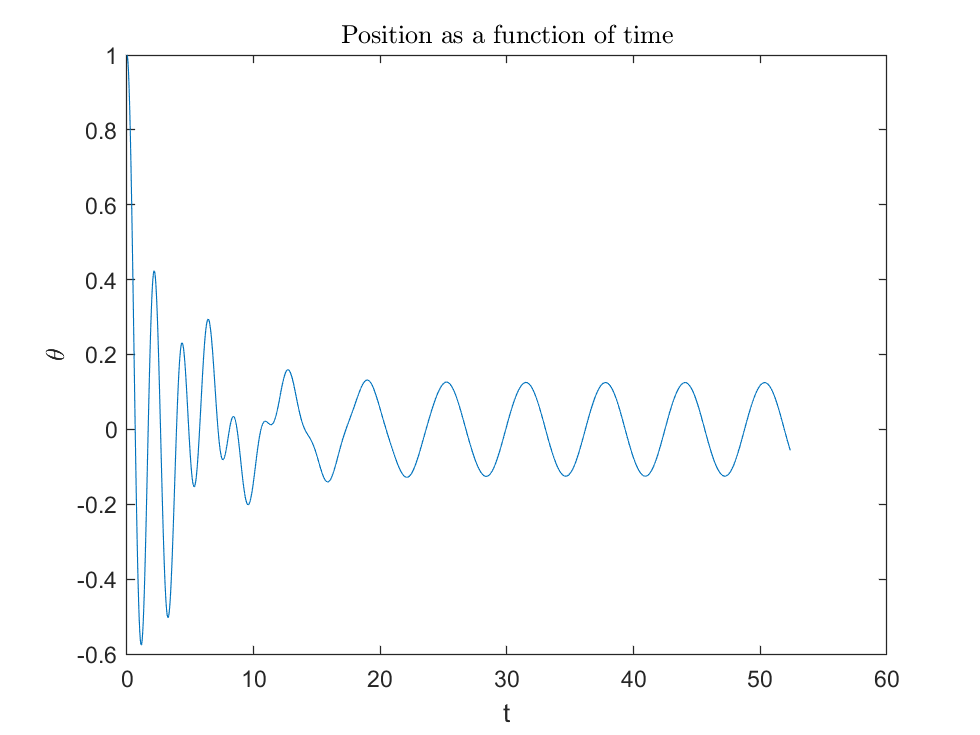

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

thetad0 = 0;
theta0 = 1;
omega = 4;
[t,w] = pendulum_damp_driven(R,theta0,thetad0,gamma,omega);
ind4 = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period4 = 2*mean(diff(t(ind4(length(ind4)-10:length(ind4)-1))))

period4 = 1.5713

omega4 = 2*pi/period4

omega4 = 3.9987

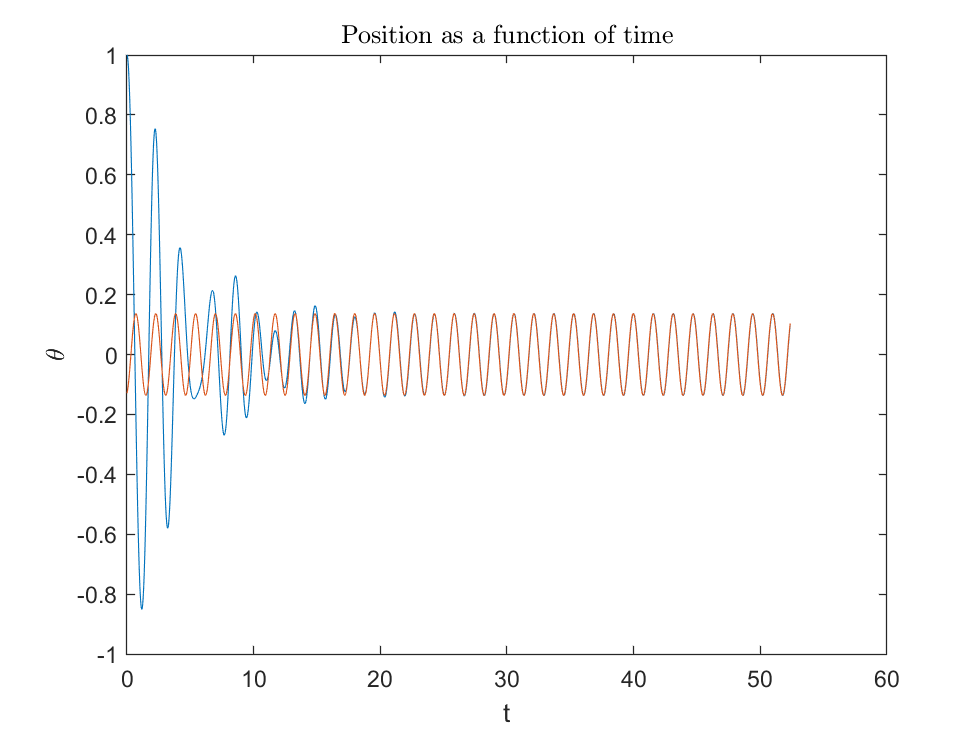

A = max(w(end-100:end,1));
delta = min(acos(w(end-150:end,2)/A)-omega*mod((w(end-150:end,1)),period4))+0.5; % phase shift
y = A*cos(omega*t + 2*pi*delta);

plot(t,w(:,1), t, y)
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

(c)  As the figure shows, the equation is verified because the two lines overlap for t>20.

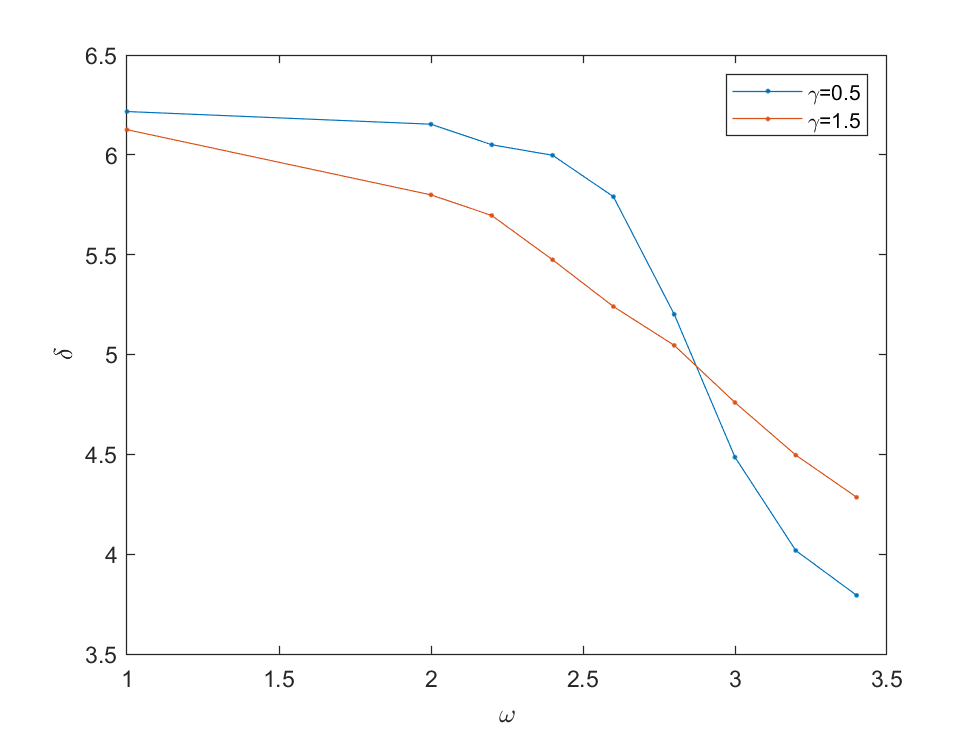

omega_array = [1,2,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
gamma_array = [0.5,1.5];
delta = zeros;
thetad0 = 0;
theta0 = 1;
for i = 1:length(omega_array)
    for j = 1:length(gamma_array)
        [t,w] = pendulum4(R,theta0,thetad0,gamma_array(j),omega_array(i));
        ind5 = find(w(:,2)>=0 & circshift(w(:,2), [-1 0]) <=0);
        delta(i,j) = mean(mod(-omega_array(i) ...
            *t((ind5(length(ind5)-3:length(ind5)-1))),2*pi));
        ind5 = zeros;
    end
end
plot(omega_array,delta(:,1),'.-', omega_array,delta(:,2),'.-')
legend('\gamma=0.5','\gamma=1.5')
xlabel('\omega')
ylabel('\delta')

Relation: as omega increases, the delta decreases.

omega=0 is special, which means the force is a constant, thus it is not a real driven pendulum case. Then delta is undefined.